# МЕТОДЫ ОПТИМИЗАЦИИ

## Семинар 7

### Общая постановка задачи оптимизации.

Терминология, в общем виде задача оптимизации формулируется как найти такой вектор параметров

### Линейная оптимизация (метод наименьших квадратов)

Будем рассматрицать задачу, когда число строк больше числа столбцов, это задача, которая возникает на практике,

$\vec{b}$ - вектор наблюдений

$\vec{x}$ - вектор параметров (переменных оптимизации)

$A$ - постоянная матрица (не зависящая от переменных оптимизации -  $\vec{x}$)

Число строк матрицы $A$ определяется  количеством измерений, а число столбцов - числом параметров оптимизации.

Геометрия 


$$A\vec{x}=\vec{b}$$


Подпространства матрицы (nxm)

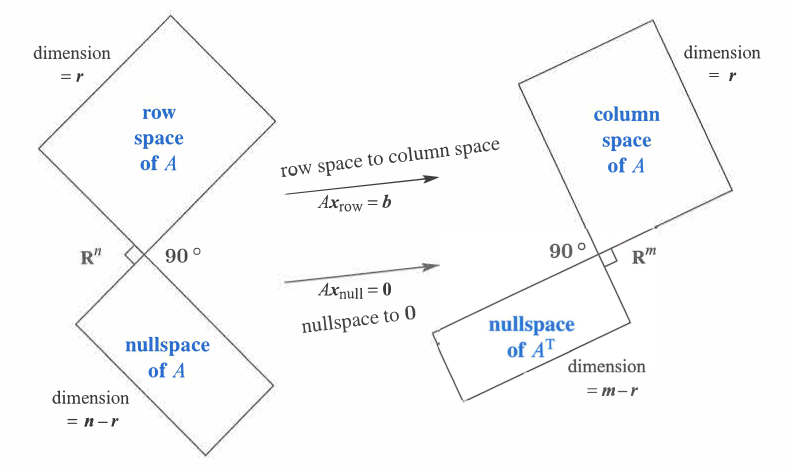

#### Системы линейных алгебраических уравнений


$$A\vec{x}=\vec{b}$$


Решим систему линейных уравнений:

clearvars
% квадратная матрица  - СЛАУ полностью определена
A = rand(10)
b = rand([10,1])
x = A\b % эквивалентно 


% матрица прямоуголная
A = rand([10,5])
b = rand([10,1])
x = A\b

Алгоритм работы функции **mldivide **или** \** 

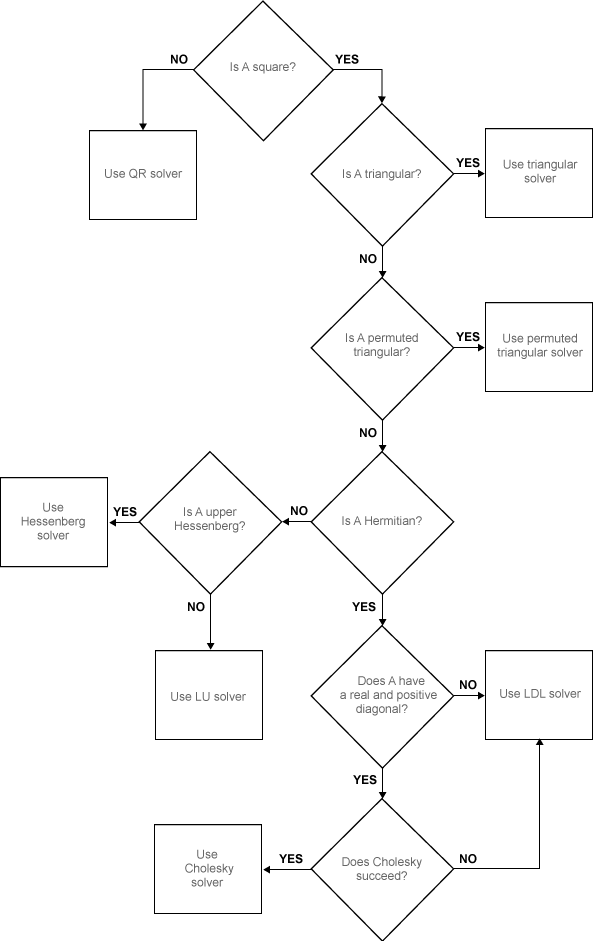

Если представить вектор $\vec b$ в виде суммы составляющих в пространстсве столбцов и в нуль пространстве 


$$A\vec{x}=\vec{b}=\vec{p} + \vec{e}$$


Картина с точки зрения линейной алгебры, если вектор $\vec{b}$ не лежит в пространстве столбцов матрицы $A$, то его можно разделить на две составляющие:

 -  нормальную пространству столбцов (то есть принадлежащая нульпространству подпространства строк)

 - и лежащую в пространстве столбцов матрицы $A$

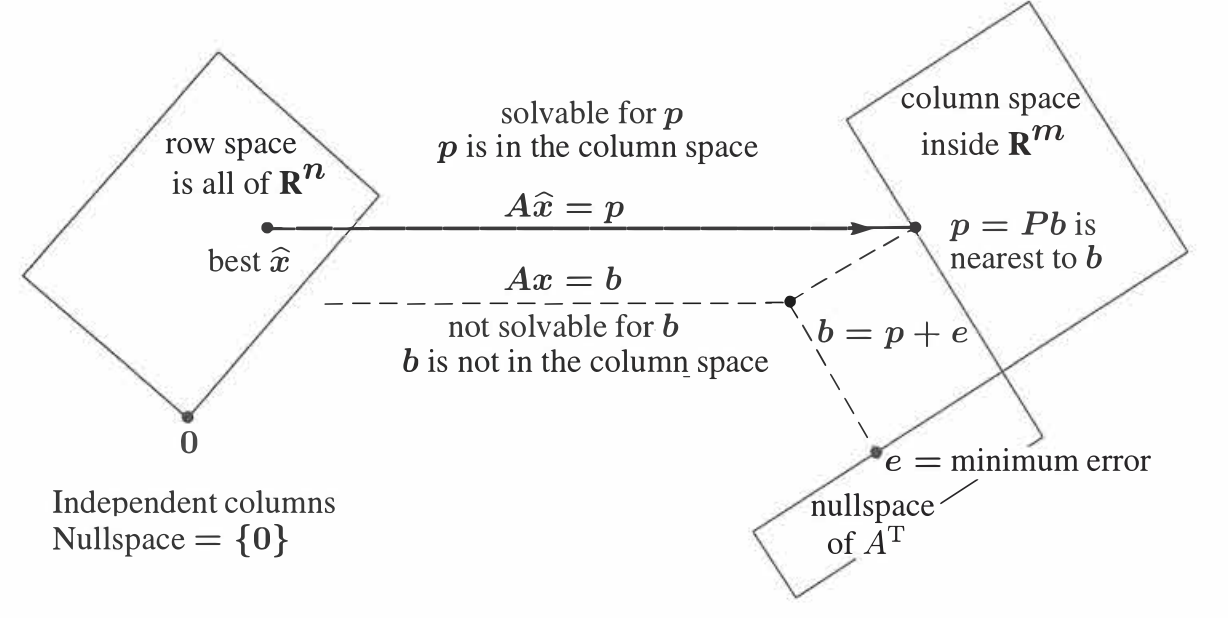

Идея в том, чтобы найти такой вектор $\vec{\hat x}$, который при действии на него матрицей $A
$ переходит в вектор $\vec{p}$ такой, что составляющая вектора $\vec{b}$, лежащая  в нуль-пространстве минимальна, то есть $\vec{e}=\vec{b} - \vec{p}$ минимальна


$$\vec{e}^T\vec{e}=||A\vec{x}-\vec{b}||^2 = (A\vec{x}-\vec{b})^T( A\vec{x}-\vec{b}) = \vec{x}^TA^TA\vec{x} -2(\vec{x}^TA^T)\vec{b}+\vec{b}^T\vec{b} $$


Условие минимума модуля ошибки $\vec{e}$ - равенство нулю градиента  $\nabla_x(\vec{e}^T\vec{e})=0$, это дает:


$$ \nabla_x(\vec{e}^T\vec{e})= 2[\nabla(\vec{x}^TA^T)]^TA\vec{x}   -2A^T\vec{b}=A^TA\vec{x} - A^T\vec{b}=0$$


Правило дифференцирования скалярного произведения: $\nabla(\vec{a}^T\vec{b})= (\nabla\vec{a})^T\vec{b} + (\vec{a})^T(\nabla\vec{b}) $

Правило дифференцирования матриц: $\nabla(A\vec{x})=A\nabla\vec{x}$, а $\nabla(\vec{x}^TA)=A^T\nabla\vec{x}$

В итоге имеет уравнение:

$A^TA\vec{x} = A^T\vec{b}$                                                                        (1)

$A^{\dagger} = (A^TA)^{-1}A^T$ - псевдо обратная матрица - оператор, который переводит произвольный вектор $\vec{b}$в вектор пространства строк матрицы $A$, если вектор $\vec{b}$ принадлежал пространству столбцов матрицы $A$ и в ноль, если принадлежал нуль-пространству матрицы $A^T$

$P_A=A(A^TA)^{-1}A^T=AA^{\dagger}$ -  оператор проецирования ветора на векторное пространство столбцов матрицы:


$$P_A \vec{b}=\vec{p}$$


% Проекция вектора на пространство столбцов матрицы из двух столбцов
 
clearvars
% генерим случаные вектора в трехмерном пространстве

b =     0.1462
   -0.4320
   -0.5572


a1 = 2*(0.5 - rand(3,1)); 

A =    -0.0883   -0.0282
   -0.3980    0.0393
    0.8419   -1.0676


a2 = 3*(0.5 - rand(3,1));

PA =     0.0844    0.2758    0.0344
    0.2758    0.9169   -0.0104
    0.0344   -0.0104    0.9987


R = [0.72, -50.7,161.3 ];% модуль-тетта-фи - сферическая система координат дял трехмерного вектора

bpar =    -0.1260
   -0.3500
   -0.5469


r = R(1);thetta = R(2);phi = R(3);

bper =     0.2722
   -0.0820
   -0.0102


fig1


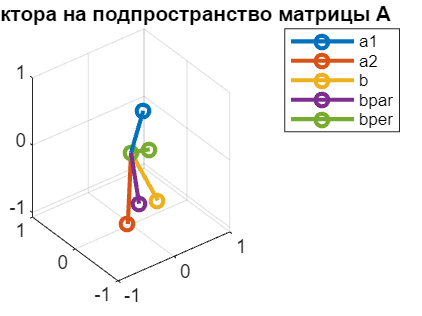

b = [r*cosd(thetta)*sind(phi);r*cosd(thetta)*cosd(phi);r*sind(thetta)] % некоторый вектор

A = [a1,a2]
PA = A*inv(A'*A)*A' % матрица проецирования
bpar = PA*b % составляющая вектора в пространстве столбцов
bper = b - bpar  % составляющая вектора перпендикулярная пространству столбцов
draw_vector([],'Проекция вектора на подпространство матрицы A',["a1" "a2" "b" "bpar" "bper"],"vector",a1,a2, b,bpar,bper);

**Как считать**

При помощи QR факторизации:

$A=QR$ ($R$ - квадратная матрица, $Q$ - ортогональная матрица)

QR-факторизация дает: $A^{\dagger}=(R^TQ^TQR)^{-1}R^TQ^T=(R^TR)^{-1}R^TQ^T=R^{-1}Q^T$

$A = U\Sigma V^T$  ($U,V$ - ортонормированные матрицы, $Q$ - ортогональная матрица)

SVD - разложение дает: $A^{\dagger}=(R^TQ^TQR)^{-1}R^TQ^T=(R^TR)^{-1}R^TQ^T=R^{-1}Q^T$

A = rand(100,2);
b = rand(100,1);
[Q,R] = qr(A,"econ") %econ значит, что возращается не полная матрица R и Q, а только размером с ранг данных

Q =    -0.0711   -0.1664
   -0.1052   -0.0557
   -0.1388   -0.0789
   -0.0450   -0.0146
   -0.0667   -0.1573
   -0.0923   -0.1357
   -0.0739    0.0086
   -0.0151   -0.0015
   -0.1240   -0.0565
   -0.0054   -0.0163


R =    -6.0049   -4.4932
         0   -3.7235


%[Q,R] = qr(A)

Q =    -0.0711   -0.1664   -0.1422   -0.0454   -0.0754   -0.0995   -0.0727   -0.0150   -0.1262   -0.0063   -0.0774   -0.0128   -0.1598   -0.0827   -0.1477   -0.0687   -0.1357   -0.0465   -0.1533   -0.1388   -0.0680   -0.1062   -0.0916   -0.1520   -0.0438   -0.0039   -0.1437   -0.0499   -0.0463   -0.1101   -0.0608   -0.1398   -0.1374   -0.1478   -0.0623   -0.1232   -0.0242   -0.1052   -0.1167   -0.0277   -0.0930   -0.1409   -0.0482   -0.0400   -0.1402   -0.0777   -0.0351   -0.0482   -0.1126   -0.0916
   -0.1052   -0.0557   -0.0713   -0.0121   -0.1543   -0.1311    0.0130   -0.0007   -0.0496   -0.0160   -0.1058   -0.1131    0.0307    0.0648    0.0491   -0.0900    0.1835   -0.0730   -0.0469    0.1587   -0.0351   -0.0458    0.0406   -0.0673   -0.1422   -0.0550    0.0366   -0.1877   -0.0988   -0.0675   -0.1772   -0.0525    0.1518    0.1491    0.0413    0.1619    0.0308   -0.0287   -0.0165   -0.2300   -0.0857    0.1068   -0.0780   -0.0200   -0.0201    0.0734   -0.1693   -0.1699   -0.0620    0

R =    -6.0049   -4.4932
         0   -3.7235
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0
         0         0


[u,S,v] = svd(A,"econ","vector");

invApseudo = v*diag(1./S)*u'

invApseudo =    -0.0216    0.0063    0.0073    0.0046   -0.0205   -0.0119    0.0140    0.0022    0.0093   -0.0024   -0.0101   -0.0216    0.0313    0.0264    0.0333   -0.0081    0.0595   -0.0080    0.0141    0.0548    0.0033    0.0070    0.0228    0.0096   -0.0229   -0.0109    0.0300   -0.0314   -0.0134    0.0031   -0.0276    0.0108    0.0531    0.0542    0.0183    0.0530    0.0102    0.0104    0.0147   -0.0437   -0.0034    0.0443   -0.0088    0.0021    0.0176    0.0275   -0.0299   -0.0280    0.0046    0.0202
    0.0447    0.0150    0.0212    0.0039    0.0422    0.0364   -0.0023    0.0004    0.0152    0.0044    0.0294    0.0303   -0.0057   -0.0160   -0.0108    0.0250   -0.0467    0.0202    0.0149   -0.0401    0.0104    0.0138   -0.0094    0.0203    0.0385    0.0147   -0.0075    0.0507    0.0270    0.0197    0.0481    0.0162   -0.0383   -0.0374   -0.0100   -0.0412   -0.0078    0.0093    0.0062    0.0616    0.0242   -0.0262    0.0215    0.0059    0.0075   -0.0183    0.0456    0.0460    0.

#### Полиномиальная аппркосимация

Полиномиальный фиттинг  - частный случай линейной оптимизации

Пусть $\vec t = \matrix {t_1 \cr \vdots \cr t_N}$ - вектор независиммых переменных, полиномиальная функция имеет вид:


$$\vec y (\vec t)= a_1 \vec  {t}^0 +\vec{t}^1 + ... + \vec{t}^{P-1} =[\matrix {1 & \dots & t_1^{i-1} & \dots &t_1^{P-1} \cr  \vdots & & \vdots & & \vdots \cr 1 & \dots & t_j^{i-1}& \dots & t_j^{P-1} \cr   \vdots & & \vdots & & \vdots \cr t_j^{i-1}& \dots & t_j^{P-1} & \dots & t_{N}^{P-1} } ] [\matrix{a_1 \cr \vdots \cr a_i \cr \vdots \cr a_P}] = V\vec{a}$$


$V$ - матрица Вандермонда - матрица размером [NxP], $\vec{a}$ - вектор параметров линейной оптимизации.

Если число измеренных точек (N) больше числа коэффициентов полинома, то, данная переопределенная система имеет решение в форме псевдообратной матрицы $\vec{a}$.

% параметры экспериментальных данных
N=100 % число точек измерения

N = 100

t = transpose(linspace(-1,1,N)) % независисмые переменные

t =    -1.0000
   -0.9798
   -0.9596
   -0.9394
   -0.9192
   -0.8990
   -0.8788
   -0.8586
   -0.8384
   -0.8182


type_experiment = "stand" % тип реальнйо функции 

type_experiment = "stand"

P = 3 % степень полинома

P = 3

a1=1;
a2=1.992;
a3=0.554;
a4=0.0218;
a5=-0.55829;
e = 11.02; % амплитуда шумов 
a_real = [a1;a2;a3;a4;a5];
% заполняем массив "экспериментальных" данных
y = 0;
Pfun = producing_function(type,t);
for ii = 1:P
    y = y + a_real(ii)*t.^(ii-1);
end
y = y + e*mean(y)*randn(size(y))/100;
ax = get_next_ax();

fig1


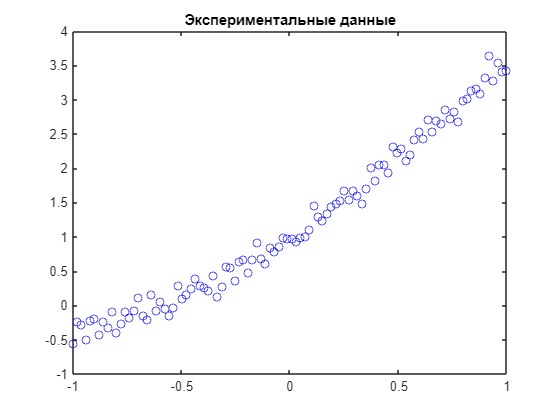

plot(ax,t,y,"ob");
title(ax,"Экспериментальные данные")


% параметры полинома которым фитим
type_fit = "leg"
Pfit = 3
V = vandermatrix(t,Pfit,type_fit); % формируем матрицу Вандермонда
tb = table();
tb.a_real = a_real(1:Pfit);
tb.a_fitted_qr = V\y; % решается методом qr факторизации

tb.a_fitted_pinv= pinv(V)*y;% решает путем SVD разложения матрицы
tb.a_lsqr = lsqminnorm(V,y) ; % минмизирует норму x

a_polyfit = transpose(polyfit(t,y,Pfit-1)); 
tb.a_polyfit = a_polyfit(end:-1:1);
tb
ax = get_named_ax("Сравнение различных способ решения задачи линейной оптимизации");
plot(ax,t,y,"o")
hold(ax,"on");
    plot(t,V*tb.a_fitted_qr,'+r')
    plot(t,V*tb.a_fitted_pinv,'g',"Marker","diamond")
    plot(t,V*tb.a_lsqr,'c')
    plot(t,polyval(a_polyfit,t),'m')
hold(ax,"off")
legend(ax,["y" "y = A*(A\\y)" "y = A*(pinv(A)*y)" "y=A*lsqrminnorm(A,y)" "Polyfit"],Location="bestoutside")

Сравнение скорости решения:

tm = table();
tm.t_fitted_qr = timeit(@()V\y,1); % решается методом qr факторизации
tm.t_fitted_pinv= timeit(@()pinv(V)*y,1); % решается через СВД разложение
tm.t_lsqr = timeit(@()lsqminnorm(V,y),1) ; % решается минимизацийе нормы стадартного отклонения итерационным способом
tm.t_polyfit = timeit(@()polyfit(t,y,Pfit-1),1);
tm

polynomial_degree = 20;
V_leg = vandermatrix(t,polynomial_degree,"leg"); % формируем матрицу Вандермонда
V_stand = vandermatrix(t,polynomial_degree,"stand");
S_leg = svds(V_leg,polynomial_degree);
S_stand = svds(V_stand,polynomial_degree);
N = 1:polynomial_degree;
plot(get_next_ax(),N,(diag(S_stand)),"or",N,(diag(S_leg)),"+b")
leg_rank = rank(V_leg)
stand_rank = rank(V_stand)
plot(get_next_ax([],{'title',text(1,1,"Полиномы Лежандра")}),V_leg )
plot(get_next_ax([],{'title',text(1,1,"Стандартный Базис")}),V_stand)



#### Оценка погрешности полиномиальной аппроскимации

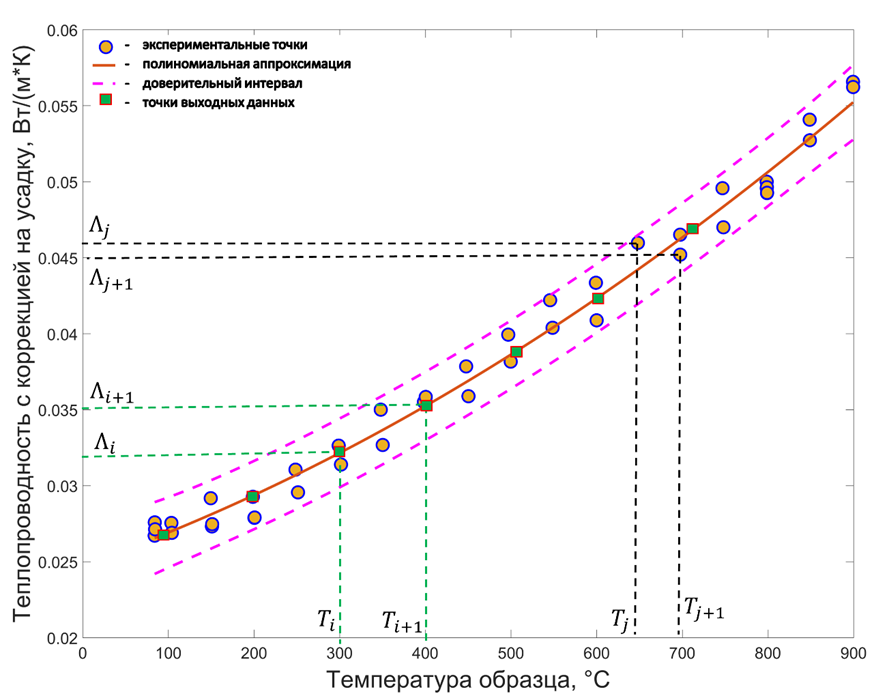

#### Полиномиальный фиттинг в матлаб

#### Оптимизация ортогональными полиномами

### Нелинейная оптимизация без ограничений 

#### Методы, использующие информацию с предудыщей итерации 

function [V,s] = vandermatrix(t,P,type,polyprod_function)
arguments
    t double
    P (1,1) double {mustBeInteger,mustBePositive} = 2
    type (1,1) string {mustBeMember(type,["stand" "leg" "trig" "custom"])} = "stand"
    polyprod_function =[]
end
% создаем матрицу Вандермонда
% type - тип полинома (стандартный базис, полиномы лежандра,
% тригонометрические полиномы)
    t = t(:);
    N = numel(t);
    V = zeros(N,P);
    if ~(type=="custom")
        [Pfun,s] = producing_function(type,t); % возвращаем производящую функцию для колонки матрицы вандермонда
    else
        assert(~isempty(polyprod_function)||~isa(polyprod_function,"function_handle"),"Если выбрана кастомная производящая функция, то нужно ее предоставить")
        s = normalize(t);
        Pfun = @(i)polyprod_function(i,s.x);
    end
    for jj = P:-1:1
        V(:,jj) = Pfun(jj);
    end
end
function norm_struct = normalize2(t)
% функция возвращает стурктуру, в которой хранятся данные для нормировки
    if ~issorted(t)
        t = sort(t,"ascend"); 
    end
    tmin = t(1);
    tmax = t(end);
    x = 2.0*((t - tmin) / (tmax - tmin))- 1; 
    norm_struct = struct("tmin",tmin,"tmax",tmax,"x",x); %t,(max(t) - min(t))    
end
function t = denormalize2(s)
    t = 0.5*(s.x + 1.0)*(s.tmax - s.tmin) + s.tmin;
end
function Pn = leg_poly(i,t) % производящая функция для полиномов Лежандра 
    persistent P 
    persistent tleg
    leg_type = 'norm';
    if isempty(tleg)||isempty(P)||(~isequal(t,tleg))
        P = transpose(legendre(i-1,t,leg_type)); % встроенная функция по сути возвращает уже матрицу Вандермонда
        tleg = t;
    end
    if i<=size(P,2)
        Pn = P(:,i);
        return
    end
    P = transpose(legendre(i,t,leg_type));
    tleg = t;
    Pn = P(:,end);
end
function Pn = trig_poly(i,t) % производящая функция для тригонометрических полиномов
    if i==1
        Pn  = ones(size(t));
        return
    end
    if mod(i,2)==0
        Pn = cos(i*t*pi);
    else
        Pn = sin(i*t*pi);
    end
end
function [P,s] = producing_function(type,t)
% функция возвращает производящую функцию для полинома
    s = normalize2(t);
    switch type
        case "stand" % стандартный базис полинома
          P = @(i) s.x.^(i-1);  
        case "leg" % полиномы Лежандра
          P = @(i) leg_poly(i,s.x); 
        case "trig" % тригонометрический базис
          P = @(i) trig_poly(i,s.x);  

    end
    
end
function [new_ax,fig_handle] = get_next_ax(index, axes_name_value_pairs)
% функция, которая возвращает новые оси на новой фигуре (нужна чтобы
% кратинки в ливскрипте нормально строились)
    arguments
        index = []
        axes_name_value_pairs cell = {}
    end
    persistent N;
    if isempty(index)
        if isempty(N)
            N=1;
        else
            N  = N+1;
        end
        fig_handle = figure(N);        
        clf(fig_handle);
        new_ax = axes(fig_handle,axes_name_value_pairs{:});
        disp("fig"+ N)
    else
        fig_handle = figure(index);
        clf(fig_handle);
        new_ax = axes(fig_handle,axes_name_value_pairs{:});    
    end
end
function ax = get_named_ax(title_string)
    ax = get_next_ax();
    title(title_string);
end
function ax = draw_vector(ax,ttl,names,type,varargin)
% функция строит двух- и трех-мерные вектора, а также рассеянные данные из
% матрицы
% ax - оси (если пустые, то создаются новые)
% ttl - заголовок картинки
% names - имена векторов
% type:
%       "vector" - аргументы, которые передаются после интерпретируются
%                   как отдельные вектора
%       "point"  - в этом случае передается матрица в качестве аргумента и
%       столбцы матрицы строятся при помощи функций scatter и scatter3 d
%       в зависимости от размерности массива
    arguments
        ax =[]
        ttl string =strings(0,1)
        names string =strings(0,1)
        type string {mustBeMember(type,["vector" "point"])}="vector"
    end
    arguments (Repeating)
        varargin double
    end
    was_empty = isempty(ax); % это признак того, что все строится на новых осях
    if was_empty
        ax = get_next_ax();
    else
        hold(ax,"on");
        % if ~isempty(ax.Legend)
        %     leg_before = ax.Legend.String;
        % else
        %     leg_before = strings(0,1);
        % end
    end
    
    if strcmp(type,"vector")
        is_3D = numel(varargin{1})==3;
            if is_3D
                [x,y,z]  = make_xy(varargin{1});
                plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y,z] = make_xy(varargin{iii});
                        plot3(ax,x,y,z,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off                
            else
                [x,y]  = make_xy(varargin{1});
                plot(ax,x,y,'LineWidth',2,'Marker','o');
                hold on 
                for iii = 2:numel(varargin)
                        [x,y]  = make_xy(varargin{iii});
                        plot(ax,x,y,'LineWidth',2,'Marker','o');
                end
                grid on
                hold off
            end
            if isempty(names)||(numel(names)~=numel(varargin))
                legend(ax,string(1:numel(varargin)));
                
            else
                % if ~was_empty
                %      names= [names(:);leg_before(:)];
                % end
                legend(ax,names);
            end
            xlim(ax,[-1 1]);
            ylim(ax,[-1 1]);
            if ~isempty(ttl)
                title(ax,ttl);
            end
    else
        %data_number = numel(varargin); % число массивов данных
        is_3D = numel(varargin)==3;
        data = varargin{1};
        if size(data,2)>1
            data = transpose(data);
            is_transpose = true;
        else
            is_transpose = false;
        end
        if ~is_transpose
            for iii = 2:numel(varargin)
                data = [data,varargin{iii}];
            end
        else
            for iii = 2:numel(varargin)
                data = [data,transpose(varargin{iii})];
            end            
        end

        if is_3D
            scatter3(ax,data(:,1),data(:,2),data(:,3));
        else
            scatter(ax,data(:,1),data(:,2));
        end

    end
    if ~was_empty
            hold(ax,"off");
    end
end
function [x,y,z]  = make_xy(col)
% добавляет к координатам вектора нули так, чтобы при помощи функции plot
% строилась линия
    switch numel(col)
        case 1
            x = [col(1)];
            y = 0;
            z = 0;
        case 2
            x = [0 col(1)];
            y = [0 col(2)];
            z = zeros(1,2);
        case 3
            x = [0 col(1)];
            y = [0 col(2)];
            z = [0 col(3)];
    end
end
% function [bpar,bper,ang,P] = projection_matrix(A,b)
% % функция считает угол между вектором и пространством столбцов матрицы A
%     for ii =1:size(A,2)
%         A(:,ii) = A(:,ii)/norm(A(:,ii));
%     end
%     beta = A*transpose(A)*b;
%     beta = beta/norm(beta); % нормируем вектор beta
%     Pbeta = beta*transpose(beta); % оператор проектирования вектора на 
%     bpar = Pbeta*b;
%     bper = b-bpar;
%     ang = rad2deg(acos(norm(bpar)/norm(b)));
% end